# Implementing vehicle dynamic model and waypoints generator algorithm into MOBATSim

This document introduces the vehicle dynamic model's implementation, along with the waypoints generator and pure pursuit controller into MOBATSim. This implementation aims to make MOBATSim more practical by enabling lateral movement control. The movement of a vehicle would be more realistic, and this gives MOBATSim more extendibility for further development.

## Changes in prepare_simulator.m

The prepare_simulator.m file loads all pre-defined driving scenarios and vehicle parameters required for simulation. 

prepare_simulator;

For convenience consideration, we add several new codes:

line3

clc;% clear Command Window

line76

figure('Name','waypoints');
hold on

This is for visualizing simulation results. It will dramatically slow down the simulation speed. So comment this out if you don't want to debug the code.

line80

v2_Xi = Map.waypoints(Vehicle2.pathInfo.startingPoint,1);
v2_Yi = -Map.waypoints(Vehicle2.pathInfo.startingPoint,3);

These two parameters are the initial position of Vehicle2. The vehicle position in the "Vehicle" class is in [x y z] format, which needs to be transferred to [x z y] to be used in the vehicle dynamic model. Furthermore, the z-axis in the "Vehicle" class needs to be reversed to plot correctly. The transformation between different coordinate systems will be explained later.

## Changes in Vehicle.m

We create a new variable to store the next ten reference waypoints for each vehicle :

obj.dynamics.reference_waypoints = [0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;];

Differential to the original coordinate, the reference waypoints are in [x z y] format corresponding to the following local coordinate:

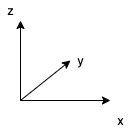

Mind that all new variables with 'local' prefix are in local coordinate. In order to transform positions in MOBATSim coordinate to local coordinate, the following process should proceed:


$$\left[ \begin{array}{c}
x \\
z\\
y 
\end{array}
\right ]_{local}=
\left[ \begin{array}{c}
x \\
y\\
-z 
\end{array}
\right ]_{m}$$


where subscript 'local' and 'm' represent local coordinate and MOBATSim coordinate.

## Changes in MOBATSim.slx

All changes are only in vehicle 2:

1.Replace Matlab system 'VehicleKinematics' with 'VehicleKinematic_Qihang'. Detail information will be explained later.

2. Add 'Pure Pursuit' and 'Wheel Steering Angle Formulation' blocks for pure pursuit control.

3. Add the 'Vehicle Body 3DOF Dual Track' block to simulate a real vehicle's movement. Inputs of this block are wheel steering angle and reference speed. Outputs are vehicle information such as position, steering angle, and speed. These data are then used in 'VehicleKinematic_Qihang'.

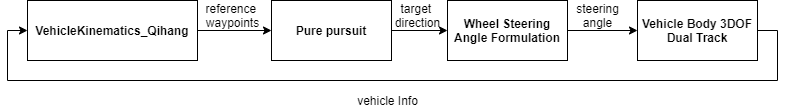

Except for the 'VehicleKinematic_Qihang' Matlab system, the other three blocks are pre-defined blocks from the Matlab toolbox. Detailed information about these blocks is available in Matlab documentation.

## Algorithm for waypoints generation in 'VehicleKinematic_Qihang'